clear 
load('E:\Data\jcp\abf\allabf.mat')

for n=1%:10
    clearvars -except matfile n
    filename=cell2mat(matfile(n));
    
    % name='/Users/platel/Desktop/exp/Arnaud VIncent/A529/20150224/15224003.abf'
    % filename='E:\Data\jcp\abf\abf_444176_111423_plane0_002\2023_11_14_0002.abf';
    
    [path,name,ext] = fileparts(filename);
    path =[path '\'];%pc
    
    savepath='E:\Data\jcp\abf\'
    
    [data sampling_rate h]= abfload(filename);
    [amplitude,locs] = findpeaks(data(:,1),'MinPeakHeight',4,'MinPeakDistance',500);
    save([filename,'time.mat'],'locs')  
end

savepath = 'E:\Data\jcp\abf\'

** abfload
opening E:\Data\jcp\abf\abf_444176_111423_plane0_002\2023_11_14_0002.abf..
data were acquired in gap-free mode
total length of recording: 1921.4 s ~ 32 min
memory requirement for complete upload in matlab: 3665 MB


% sampling_rate=numel(data)/

% Sr = 2e4;
% Nz = 1000;
% NFilms = 2;



% ch1 = downsample(data(:,1),10);%imagerie
ch1 = data(:,1);%imagerie

 name='/Users/platel/Desktop/exp/aurelie/abf_444176_111423_plane0_002/2023_11_14_0002.abf'
 data = abfload(name);
 [amplitude,locs] = findpeaks(data(:,1),'MinPeakHeight',4,'MinPeakDistance',500);
 realtime=locs(Trace) ;

  % text(locs,-1,'*','FontSize',20);


for i=1:numel(locs)-1
    interframe(i)=(locs(i+1)-locs(i))*sampling_rate;
end

max (interframe)
min(interframe)

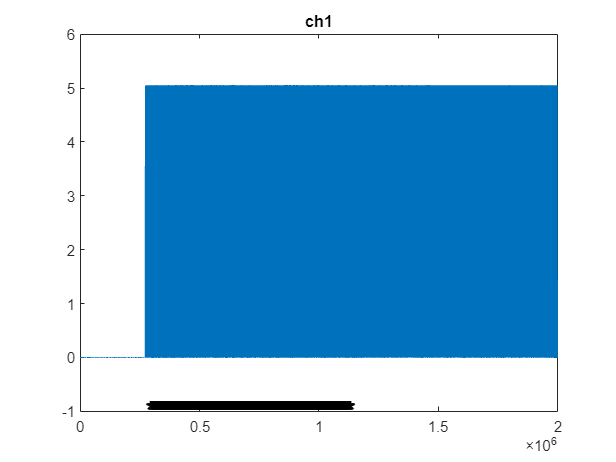

figure
plot(ch1(1:2000000))
for i=1:500
    text(locs(i),-1,'*','FontSize',20);
end
title('ch1')

ch2 = downsample(data(:,2),10);%tour de tapis
figure
plot(ch2)
title('ch2')
ch3 = downsample(data(:,3),10);%electrophy
figure
plot(ch3)
title('ch3')
ch4 = downsample(data(:,4),10); % vitesse
figure
plot(ch4)
title('ch4')
ch5 = downsample(data(:,5),10); % vitesse
figure
plot(ch5)
title('ch5')

ch5 = data(:,5); % vitesse
 ephys = sgolayfilt(ch5',3,5)';%was at 5
 

figure

plot(ephys(1:100000))
title('ephys')